clear all 
clf

syms I

%importing data sets
d_404 = readmatrix("404.csv")

d_404 = 	1.0e+03 *

   -1.9970    0.0005   -0.3634    0.0030
   -1.9060    0.0005   -0.3574    0.0010
   -1.8880    0.0005   -0.3534    0.0020
   -1.8290    0.0005   -0.3494    0.0010
   -1.8110    0.0005   -0.3464    0.0010
   -1.7900    0.0005   -0.3434    0.0010
   -1.7520    0.0005   -0.3334    0.0010
   -1.7180    0.0005   -0.3264    0.0010
   -1.6860    0.0005   -0.3154    0.0010
   -1.6360    0.0005   -0.2974    0.0010


d_435 = readmatrix("435.csv")

d_435 = 	1.0e+03 *

   -1.9630    0.0005   -0.3924    0.0010
   -1.5300    0.0010   -0.3704    0.0010
   -1.4440    0.0005   -0.3544    0.0020
   -1.4080    0.0005   -0.3474    0.0010
   -1.3590    0.0005   -0.3334    0.0020
   -1.3090    0.0005   -0.3104    0.0010
   -1.2490    0.0005   -0.2494    0.0010
   -1.2080    0.0005   -0.1814    0.0010
   -1.1010    0.0005    0.1416    0.0020
   -1.0000    0.0005    0.6776    0.0010


d_546 = readmatrix("546.csv")

d_546 = 	1.0e+03 *

   -1.9950    0.0005   -0.2864    0.0010
   -1.7810    0.0005   -0.2814    0.0010
   -1.5030    0.0005   -0.2784    0.0010
   -1.2910    0.0005   -0.2764    0.0020
   -0.9940    0.0005   -0.2714    0.0010
   -0.9400    0.0005   -0.2834    0.0020
   -0.8990    0.0005   -0.2684    0.0010
   -0.8500    0.0005   -0.2604    0.0010
   -0.8000    0.0005   -0.2474    0.0010
   -0.7620    0.0005   -0.2344    0.0010


d_577 = readmatrix("577.csv")

d_577 = 	1.0e+03 *

   -1.5270    0.0010   -0.1384    0.0010
   -1.2990    0.0010   -0.1344    0.0010
   -1.0080    0.0005   -0.1314    0.0010
   -0.8490    0.0005   -0.1294    0.0010
   -0.7980    0.0005   -0.1284    0.0010
   -0.7010    0.0005   -0.1194    0.0010
   -0.6580    0.0005   -0.1034    0.0010
   -0.6250    0.0005   -0.0744    0.0010
   -0.6040    0.0005   -0.0444    0.0010
   -0.5490    0.0005    0.1496    0.0010



%calculating coefficients
%

%error plotting source: https://uk.mathworks.com/help/matlab/ref/errorbar.html
%format used: errorbar(x,y,yneg,ypos,xneg,xpos,'o')
errorbar(d_404(:,1),d_404(:,3),d_404(:,4),d_404(:,4),d_404(:,2),d_404(:,2),"o")
hold on

%plotting poly
[c_404,s_404] = polyfit(d_404(:,1),d_404(:,3),3)

c_404 = 	1.0e+04 *

    0.0000    0.0000    0.0039    2.3126


s_404 = struct with fields:
        R: [4×4 double]
       df: 8
    normr: 33.2899


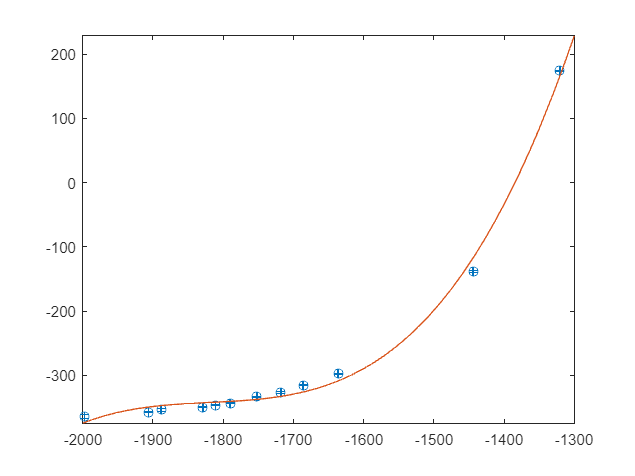

fplot(c_404(1)*I^3 + c_404(2)*I^2 + c_404(3)*I + c_404(4))
xlim([-2000 -1300])